# Actividad 1 (Mapeo de coordenadas)

Implementar el código requerido para generar un **mapeo** del siguiente sistema global al sistema local de referencia del robot móvil y viceversa.

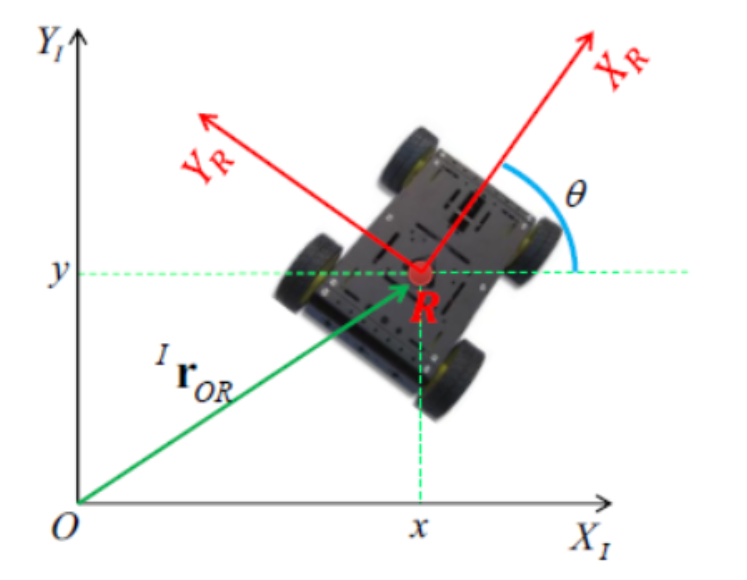}

Obtener el mapeo de las siguientes coordenadas inerciales, hacia un marco de referencia local y comprobar si se obtienen las coordenadas iniciales con el mapeo inverso

% Limpieza de pantalla
clear all
close all
clc

tic

Para empezar Se trabaja con dos sistemas de referencia:

- **Inercial:** Un marco de referencia fijo en el espacio (coordenadas dadas en la tabla).

- **Local:** Un sistema de referencia que ha sido rotado respecto al inercial.


% Suponiendo que las coordenadas inerciales se dan como (x, y, theta)
coordenadas_inerciales = [
   -5   9   -2;   
   -3   8   63;   
    5  -2   90;   
    0   0  180;   
   -6   3  -55;  
   10  -2   45;   
    9   1   88;  
    5   2   33;   
   -1  -1   21;   
    6   4  -40;  
    5   7   72;  
    7   7   30;   
   11  -4  360;   
   20   5  270;  
   10   9  345;  
   -9  -8    8;  
    1   1   60;   
    3   1  -30;  
   15   2  199;   
  -10   0  300;   
];

% Letras para los incisos
letras = 'abcdefghijklmnñopqrs';

De igual forma se usa una matriz de rotación para transformar coordenadas de un sistema de referencia a otro  Por otro lado el vector de posición inercial es la representación de un punto en el marco de referencia global (inercial). En el código, este vector se define como:

% Recorremos cada conjunto de coordenadas inerciales
for i = 1:size(coordenadas_inerciales,1)
    
    % Extraemos x, y, theta (en grados si es tu caso)
    x_i  = coordenadas_inerciales(i,1);
    y_i  = coordenadas_inerciales(i,2);
    th_i = coordenadas_inerciales(i,3);  % En grados, por ejemplo
    
    % Si el ángulo está en grados, convertimos a radianes
    th_rad = deg2rad(th_i);
    
    % Definimos el vector de posición (en 3D, con la tercera componente = 0)
    Pos_i = [x_i; y_i; 0];
    
    % Matriz de rotación en torno a Z para el ángulo th_rad
    Rot_i = [ cos(th_rad), -sin(th_rad), 0;
              sin(th_rad),  cos(th_rad), 0;
              0,            0,           1];


Multiplicamos la **matriz de rotación** por el **vector de posición inercial** para obtener su representación en el marco local:

=== Punto a ===


Posición original (x, y, θ): (-5.00, 9.00, -2.00°)


Transformación al sistema local (xL, yL, zL): (-4.6829, 9.1690, 0.0000)


Magnitud del vector local: 10.2956


Posición reconstruida (x, y, zL): (-5.0000, 9.0000, 0.0000)



=== Punto b ===


Posición original (x, y, θ): (-3.00, 8.00, 63.00°)


Transformación al sistema local (xL, yL, zL): (-8.4900, 0.9589, 0.0000)


Magnitud del vector local: 8.5440


Posición reconstruida (x, y, zL): (-3.0000, 8.0000, 0.0000)



=== Punto c ===


Posición original (x, y, θ): (5.00, -2.00, 90.00°)


Transformación al sistema local (xL, yL, zL): (2.0000, 5.0000, 0.0000)


Magnitud del vector local: 5.3852


Posición reconstruida (x, y, zL): (5.0000, -2.0000, 0.0000)



=== Punto d ===


Posición original (x, y, θ): (0.00, 0.00, 180.00°)


Transformación al sistema local (xL, yL, zL): (0.0000, 0.0000, 0.0000)


Magnitud del vector local: 0.0000


Posición reconstruida (x, y, zL): (0.0000, 0.0000, 0.0000)



=== Punto e ===


Posición original (x, y, θ): (-6.00, 3.00, -55.00°)


Transformación al sistema local (xL, yL, zL): (-0.9840, 6.6356, 0.0000)


Magnitud del vector local: 6.7082


Posición reconstruida (x, y, zL): (-6.0000, 3.0000, 0.0000)



=== Punto f ===


Posición original (x, y, θ): (10.00, -2.00, 45.00°)


Transformación al sistema local (xL, yL, zL): (8.4853, 5.6569, 0.0000)


Magnitud del vector local: 10.1980


Posición reconstruida (x, y, zL): (10.0000, -2.0000, 0.0000)



=== Punto g ===


Posición original (x, y, θ): (9.00, 1.00, 88.00°)


Transformación al sistema local (xL, yL, zL): (-0.6853, 9.0294, 0.0000)


Magnitud del vector local: 9.0554


Posición reconstruida (x, y, zL): (9.0000, 1.0000, 0.0000)



=== Punto h ===


Posición original (x, y, θ): (5.00, 2.00, 33.00°)


Transformación al sistema local (xL, yL, zL): (3.1041, 4.4005, 0.0000)


Magnitud del vector local: 5.3852


Posición reconstruida (x, y, zL): (5.0000, 2.0000, 0.0000)



=== Punto i ===


Posición original (x, y, θ): (-1.00, -1.00, 21.00°)


Transformación al sistema local (xL, yL, zL): (-0.5752, -1.2919, 0.0000)


Magnitud del vector local: 1.4142


Posición reconstruida (x, y, zL): (-1.0000, -1.0000, 0.0000)



=== Punto j ===


Posición original (x, y, θ): (6.00, 4.00, -40.00°)


Transformación al sistema local (xL, yL, zL): (7.1674, -0.7925, 0.0000)


Magnitud del vector local: 7.2111


Posición reconstruida (x, y, zL): (6.0000, 4.0000, 0.0000)



=== Punto k ===


Posición original (x, y, θ): (5.00, 7.00, 72.00°)


Transformación al sistema local (xL, yL, zL): (-5.1123, 6.9184, 0.0000)


Magnitud del vector local: 8.6023


Posición reconstruida (x, y, zL): (5.0000, 7.0000, 0.0000)



=== Punto l ===


Posición original (x, y, θ): (7.00, 7.00, 30.00°)


Transformación al sistema local (xL, yL, zL): (2.5622, 9.5622, 0.0000)


Magnitud del vector local: 9.8995


Posición reconstruida (x, y, zL): (7.0000, 7.0000, 0.0000)



=== Punto m ===


Posición original (x, y, θ): (11.00, -4.00, 360.00°)


Transformación al sistema local (xL, yL, zL): (11.0000, -4.0000, 0.0000)


Magnitud del vector local: 11.7047


Posición reconstruida (x, y, zL): (11.0000, -4.0000, 0.0000)



=== Punto n ===


Posición original (x, y, θ): (20.00, 5.00, 270.00°)


Transformación al sistema local (xL, yL, zL): (5.0000, -20.0000, 0.0000)


Magnitud del vector local: 20.6155


Posición reconstruida (x, y, zL): (20.0000, 5.0000, 0.0000)



=== Punto ñ ===


Posición original (x, y, θ): (10.00, 9.00, 345.00°)


Transformación al sistema local (xL, yL, zL): (11.9886, 6.1051, 0.0000)


Magnitud del vector local: 13.4536


Posición reconstruida (x, y, zL): (10.0000, 9.0000, 0.0000)



=== Punto o ===


Posición original (x, y, θ): (-9.00, -8.00, 8.00°)


Transformación al sistema local (xL, yL, zL): (-7.7990, -9.1747, 0.0000)


Magnitud del vector local: 12.0416


Posición reconstruida (x, y, zL): (-9.0000, -8.0000, 0.0000)



=== Punto p ===


Posición original (x, y, θ): (1.00, 1.00, 60.00°)


Transformación al sistema local (xL, yL, zL): (-0.3660, 1.3660, 0.0000)


Magnitud del vector local: 1.4142


Posición reconstruida (x, y, zL): (1.0000, 1.0000, 0.0000)



=== Punto q ===


Posición original (x, y, θ): (3.00, 1.00, -30.00°)


Transformación al sistema local (xL, yL, zL): (3.0981, -0.6340, 0.0000)


Magnitud del vector local: 3.1623


Posición reconstruida (x, y, zL): (3.0000, 1.0000, 0.0000)



=== Punto r ===


Posición original (x, y, θ): (15.00, 2.00, 199.00°)


Transformación al sistema local (xL, yL, zL): (-13.5316, -6.7746, 0.0000)


Magnitud del vector local: 15.1327


Posición reconstruida (x, y, zL): (15.0000, 2.0000, 0.0000)



=== Punto s ===


Posición original (x, y, θ): (-10.00, 0.00, 300.00°)


Transformación al sistema local (xL, yL, zL): (-5.0000, 8.6603, 0.0000)


Magnitud del vector local: 10.0000


Posición reconstruida (x, y, zL): (-10.0000, 0.0000, 0.0000)



    % 1) Transformación al marco de referencia local
    xi_local_i = Rot_i * Pos_i;

Elapsed time is 0.090758 seconds.


Se obtiene la distancia euclidiana del punto transformado al origen del marco local.

    % 2) Magnitud del vector resultante en el marco local (opcional)
    magnitud_i = sqrt( xi_local_i(1)^2 + xi_local_i(2)^2 );
    

Se usa la inversa de la matriz de rotación para regresar al sistema inercial.

    % 3) Inversa de la matriz de rotación para volver al marco inercial
    inv_Rot_i = inv(Rot_i);
    xi_inercial_recuperado = inv_Rot_i * xi_local_i;
    
    % Mostramos resultados en pantalla con mensajes modificados
    fprintf('=== Ejercicio %c ===\n', letras(i));
    fprintf('Posición original (x, y, θ): (%.2f, %.2f, %.2f°)\n', x_i, y_i, th_i);
    fprintf('Transformación al sistema local (xL, yL, zL): (%.4f, %.4f, %.4f)\n', ...
            xi_local_i(1), xi_local_i(2), xi_local_i(3));
    fprintf('Magnitud del vector local: %.4f\n', magnitud_i);
    fprintf('Posición reconstruida (x, y, zL): (%.4f, %.4f, %.4f)\n\n', ...
            xi_inercial_recuperado(1), xi_inercial_recuperado(2), xi_inercial_recuperado(3));
end

toc

En conclusión el programa realiza la transformación de coordenadas de un conjunto de puntos desde un marco de referencia inercial a un marco de referencia local mediante el uso de matrices de rotación en 2D. Primero, convierte el ángulo de rotación de grados a radianes, luego aplica una matriz de rotación para obtener la nueva posición en el sistema local y calcula la magnitud del vector transformado. Finalmente, invierte la transformación para recuperar la posición original en el marco inercial. Este procedimiento es fundamental en aplicaciones de robótica, navegación y simulación, donde es necesario cambiar entre distintos sistemas de referencia de manera precisa.